%Controlador proporcional integrante derivativo
%planta
num1 = [1];
den1 = [1 6 5 0];
Gp = tf(num1, den1)

Gp =
 
          1
  -----------------
  s^3 + 6 s^2 + 5 s
 
Continuous-time transfer function.
Model Properties



%controlador
Kp = 30;
C = tf(Kp, 1)

C =
 
  30
 
Static gain.
Model Properties



%função de transferencia do ramo direto
G = series(Gp, C);

%função de trasnferencia de malha fechada
A = 1000;
FTMF = feedback(G,1)

FTMF =
 
            30
  ----------------------
  s^3 + 6 s^2 + 5 s + 30
 
Continuous-time transfer function.
Model Properties


figure;
g = feedback(Gp, 1)

g =
 
            1
  ---------------------
  s^3 + 6 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


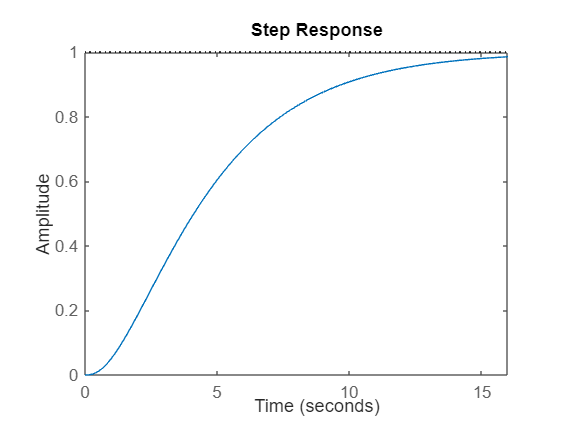

step(g, 16)

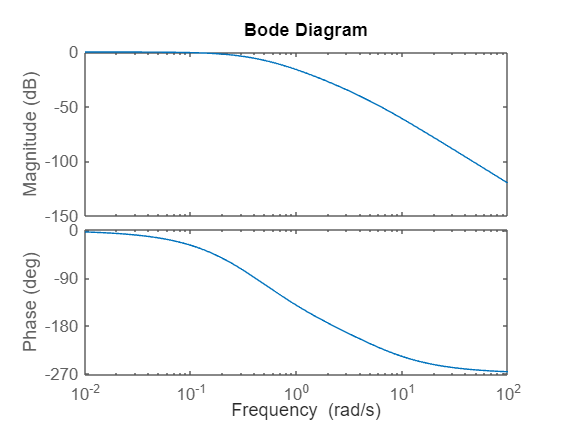

bode(g)

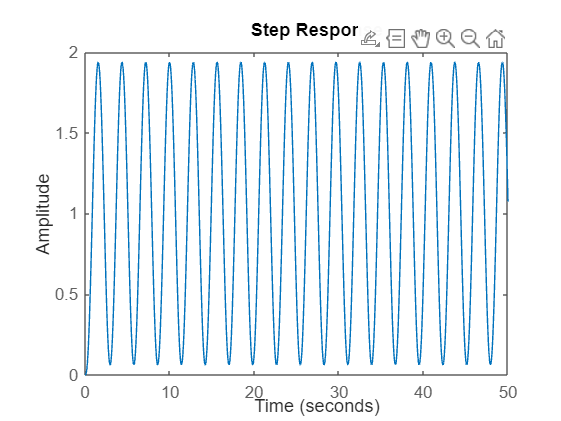

step(FTMF, 50)